%% logfile from REGBOT:
%  1    time 0.000 sec, from Naja (39)
%  2  3  4  5   (mission 0), state 2, entered (thread 1, line 0), events 0x0 (bit-flags)
%  6  7 Motor velocity ref left, right: 0.0000 0.0000
%  8  9 Motor voltage [V] left, right: 0.00 0.00
% 10 13 Wheel velocity [m/s] left, right: 0.0000 0.0000 delay 0.0000 0.0000 (sec)
% 14 15 16 17 Pose x,y,h,tilt [m,m,rad,rad]: 0 0 0 -0.655069
% 18    Battery voltage [V]
data = readtable('log_mrvwpb_00.txt',CommentStyle="%");
data = fillmissing(data,'nearest');


t = table2array(data(:,1));     % time stamps
u_L = table2array(data(:,8));   % left motor voltage
u_R = table2array(data(:,9));   % right motor voltage
v_L = table2array(data(:,10));  % left motor velocity 
v_R = table2array(data(:,11));  % right motor velocity
T_s = t(2) - t(1);              % compute sampling time

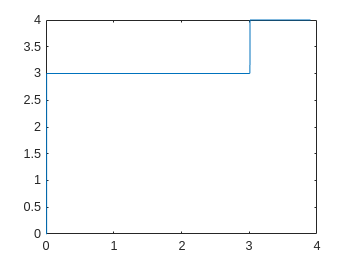

% Create a figure with subplots
figure;
plot(t,u_L)

plot(t,u_R)

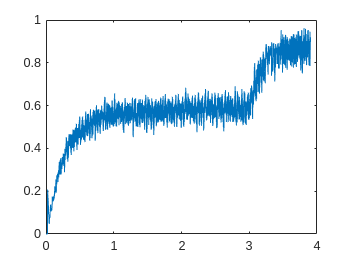

plot(t,v_L)

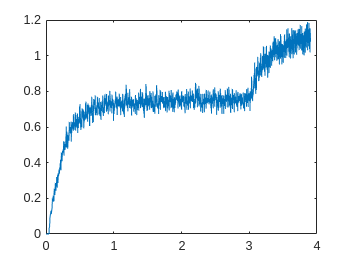

plot(t,v_R)